clc;
close all;
clear all;

m = 0.1;
M = 0.427;
l = 0.10382;
J = 8.9432*10^-4;
g = -9.81;
%fix g ee
alpha = m + M - (m^2*l^2)/(J+m*l^2)

alpha = 0.4723

beta = (J+m*l^2) - (m^2*l^2)/(m+M)

beta = 0.0018


% Continuous Time State Space
A = [0 1 0 0;
     0 0 -(m^2*l^2*g)/(alpha*(J+m*l^2)) 0;
     0 0 0 1;
     0 0 (m*g*l)/beta 0]   

A =          0    1.0000         0         0
         0         0    1.1351         0
         0         0         0    1.0000
         0         0  -57.6174         0


B = [0; 1/alpha; 0; -m*l/beta*(m+M)]

B =          0
    2.1171
         0
   -3.0952


C = [1 0 0 0; 0 0 1 0]

C =      1     0     0     0
     0     0     1     0


D = [0; 0]

D =      0
     0



sys_c = ss(A, B, C, D)


sys_c =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0   1.135       0
   x3       0       0       0       1
   x4       0       0  -57.62       0
 
  B = 
           u1
   x1       0
   x2   2.117
   x3       0
   x4  -3.095
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



% Discrete Time State Space
Ts = 0.01

Ts = 0.0100


sys_d = c2d(sys_c, Ts, 'zoh')


sys_d =
 
  A = 
              x1         x2         x3         x4
   x1          1       0.01  5.673e-05  1.891e-07
   x2          0          1    0.01134  5.673e-05
   x3          0          0     0.9971    0.00999
   x4          0          0    -0.5756     0.9971
 
  B = 
               u1
   x1   0.0001059
   x2     0.02117
   x3  -0.0001547
   x4    -0.03092
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.



Ad = sys_d.A;
Bd = sys_d.B;
Cd = sys_d.C;
Dd = sys_d.D;

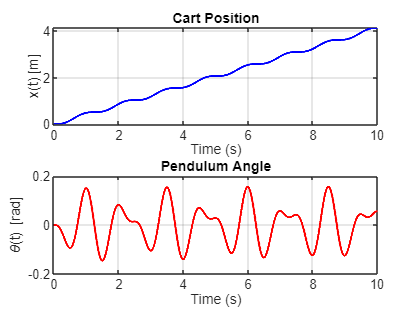

sys = ss(A,B,C,D);

%% Input: V(t) = V0 + V1*sin(wt)
V0 = 0;          % DC component
V1 = 1;          % amplitude
w  = 5;          % rad/s

t = 0:0.001:10;  % simulation time

u = V0 + V1*sin(w*t);

%% Simulation
[y, t, x] = lsim(sys, u, t);

cart_pos = y(:,1);
theta    = y(:,2);

%% Plot Results
figure;
subplot(2,1,1);
plot(t, cart_pos, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('x(t) [m]');
title('Cart Position');
grid on;

subplot(2,1,2);
plot(t, theta, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('\theta(t) [rad]');
title('Pendulum Angle');
grid on;


%% --- Sinusoidal Fitting (Estimate amplitude & phase) ---
% Fit: y = a*sin(wt) + b*cos(wt) + c

X = [sin(w*t(:)) cos(w*t(:)) ones(length(t),1)];

% For cart position
params_x = X \ cart_pos;
a_x = params_x(1);
b_x = params_x(2);
x0  = params_x(3);

x1   = sqrt(a_x^2 + b_x^2);
phi_x = atan2(b_x, a_x);

% For pendulum angle
params_th = X \ theta;
a_th = params_th(1);
b_th = params_th(2);
theta0 = params_th(3);

theta1   = sqrt(a_th^2 + b_th^2);
phi_theta = atan2(b_th, a_th);

%% Display Results
fprintf('--- Cart Position ---\n');

--- Cart Position ---


fprintf('x0 = %.4f\n', x0);

x0 = 2.0561


fprintf('x1 = %.4f\n', x1);

x1 = 0.2430


fprintf('phi_x = %.4f rad\n\n', phi_x);

phi_x = -3.0526 rad




fprintf('--- Pendulum Angle ---\n');

--- Pendulum Angle ---


fprintf('theta0 = %.4f\n', theta0);

theta0 = 0.0001


fprintf('theta1 = %.4f\n', theta1);

theta1 = 0.0933


fprintf('phi_theta = %.4f rad\n', phi_theta);

phi_theta = 3.1340 rad


% % Optimization
% % 1. Hardware Data
% % t = time vector
% % u_pwm = input PWM sine wave
% % y_meas = [x_meas, theta_meas]; % Your real encoder data
% 
% % 2. Define Known Parameters
% params.m = 0.1; 
% params.M = 0.427;
% params.l = 0.10382;
% params.g = 9.81;
% 
% % 3. Set Initial Guesses for Unknown Parameters [J, b]
% guess_0 = [0.0005, 0.1]; 
% 
% % 4. Set Physical Boundaries for fmincon
% lb = [0.0001, 0.0]; 
% ub = [0.0500, 5.0]; 
% 
% % 5. Run the fmincon Optimizer
% disp('Running fmincon optimization...');
% options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'interior-point');
% 
% % fmincon syntax: fmincon(fun, x0, A, b, Aeq, beq, lb, ub, nonlcon, options)
% best_params = fmincon(@(guess) pendulum_cost(guess, t, u_pwm, y_meas, params), ...
%                       guess_0, [], [], [], [], lb, ub, [], options);
% 
% % 6. Display the Results
% disp('--- Optimization Complete ---');
% fprintf('Identified Inertia (J): %f kg*m^2\n', best_params(1));
% fprintf('Identified Friction (b): %f N*s/m\n', best_params(2));
% 
% 
% % ==========================================
% % THE COST FUNCTION 
% % ==========================================
% function error_score = pendulum_cost(guess, t, u, y_meas, p)
% 
%     % Extract the optimizer's current guesses
%     J_guess = guess(1);
%     b_guess = guess(2);
% 
%     % Rebuild matrices with the new guesses (with correct parentheses!)
%     alpha = p.m + p.M - (p.m^2 * p.l^2) / (J_guess + p.m * p.l^2);
%     beta = (J_guess + p.m * p.l^2) - (p.m^2 * p.l^2) / (p.m + p.M);
% 
%     A = [0 1 0 0;
%          0, -b_guess/p.M, -(p.m^2 * p.l^2 * p.g)/(alpha * (J_guess + p.m * p.l^2)), 0;
%          0 0 0 1;
%          0, b_guess/(p.M*p.l), (p.m * p.g * p.l)/beta, 0];
% 
%     B = [0; 1/alpha; 0; -(p.m * p.l)/beta * (p.m + p.M)];
% 
%     C = [1 0 0 0;  
%          0 0 1 0]; 
% 
%     D = [0; 0];
% 
%     % Create system and simulate with experimental input
%     sys = ss(A, B, C, D);
%     y_sim = lsim(sys, u, t);
% 
%     % Calculate the Error Score (Sum of Squared Errors)
%     error_x = y_meas(:, 1) - y_sim(:, 1);
%     error_theta = y_meas(:, 2) - y_sim(:, 2);
% 
%     % Total error (the number fmincon is trying to crush down to zero)
%     error_score = sum(error_x.^2) + sum(error_theta.^2);
% end

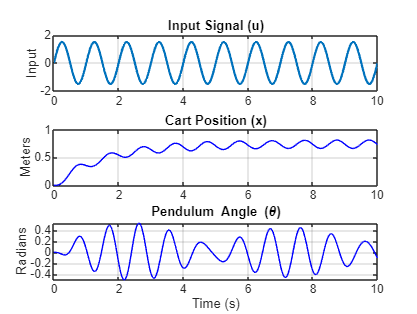

% SIMULATION
clear; clc; close all;

% 1. Define the Known Parameters
p.m = 0.1; 
p.M = 0.427;
p.l = 0.10382;
p.g = -9.81;

% 2. Define the "Secret" True Parameters
% Parameter that fmincon discover
J_true = 8.9432*10^-4; 
b_true = 0.35;

% 3. Build the True Mathematical Model
alpha = p.m + p.M - (p.m^2 * p.l^2) / (J_true + p.m * p.l^2);
beta = (J_true + p.m * p.l^2) - (p.m^2 * p.l^2) / (p.m + p.M);

A = [0 1 0 0;
     0, -b_true/p.M, -(p.m^2 * p.l^2 * p.g)/(alpha * (J_true + p.m * p.l^2)), 0;
     0 0 0 1;
     0, b_true/(p.M*p.l), (p.m * p.g * p.l)/beta, 0];
     
B = [0; 1/alpha; 0; -(p.m * p.l)/beta * (p.m + p.M)];
C = [1 0 0 0; 0 0 1 0]; 
D = [0; 0];

sys_true = ss(A, B, C, D);

% 4. Create the Sine Wave Experiment (DOE)
Ts = 0.01;              % 100 Hz sampling rate
t = (0:Ts:10)';         % Run the test for 10 seconds
freq_Hz = 1.0;          % 1 Hz sine wave
omega = freq_Hz * 2 * pi; 
amplitude = 1.5;        % Amplitude of the input force/voltage

% Generate the input sine wave
u_input = amplitude * sin(omega * t);

% 5. Simulate Hardware Response
y_perfect = lsim(sys_true, u_input, t);

% 6. Plot the Virtual Experiment
figure('Name', 'Virtual Hardware Data');
subplot(3,1,1); 
plot(t, u_input, 'LineWidth', 1.5); 
title('Input Signal (u)'); ylabel('Input'); grid on;

subplot(3,1,2); 
plot(t, y_perfect(:,1), 'b'); hold on;
title('Cart Position (x)'); ylabel('Meters'); 
grid on;

subplot(3,1,3); 
plot(t, y_perfect(:,2), 'b'); hold on;
title('Pendulum Angle (\theta)'); ylabel('Radians'); xlabel('Time (s)');
grid on;

clc;
close all;
clear all;
clear fit

data = readmatrix('Control2_ParameterTest.xlsx');

Error using readmatrix (line 171)
Unable to open file 'C:\Users\wuttipat\Desktop\work\Y4\adv control\project\Invert_pendulum_control\Control2_ParameterTest.xlsx' as a workbook. Check that the file exists, read access is available, and the file is a valid spreadsheet file.


% PWM = 20
time = data(1:50,1);
dist_20  = data(1:50, 2);
angle_20 = data(1:50, 3);

disp("PWM20 equation")

fitobject = fit(time, dist_20, 'sin2')
fitobject2 = fit(time, angle_20, 'sin2')

plot(time, dist_20)
title('Distance Fit')


plot(time, angle_20)
title('Angle Fit')

% PWM = 50
dist_50  = data(1:50, 5);
angle_50 = data(1:50, 6);
disp("PWM50 equation")
fitobject3 = fit(time, dist_50, 'sin2')
fitobject4 = fit(time, angle_50, 'sin3')

% You can easily plot the result to see how well it fits
plot(fitobject3,time, dist_50);
plot(fitobject4,time, angle_50);

% PWM = 80
disp("PWM80 equation")
dist_80  = data(1:50, 8);
angle_80 = data(1:50, 9);

fitobject5 = fit(time, dist_80, 'sin2')
fitobject6 = fit(time, angle_80, 'sin3')

% You can easily plot the result to see how well it fits
plot(fitobject5,time, dist_80);
plot(fitobject6,time, angle_80);

num_samples = 50;
samples = 1:num_samples;

% Distance
figure;
subplot(2, 1, 1);
plot(samples, dist_20, 'b', 'LineWidth', 1.5); hold on; % Blue line
plot(samples, dist_50, 'r', 'LineWidth', 1.5);          % Red line
plot(samples, dist_80, 'k', 'LineWidth', 1.5);          % Black line
title('Cart Distance vs. Sample Number');
xlabel('Sample Number');
ylabel('Distance');
legend('PWM = 20', 'PWM = 50', 'PWM = 80', 'Location', 'best');
grid on;


% Angle
subplot(2, 1, 2); 
plot(samples, angle_20, 'b', 'LineWidth', 1.5); hold on;
plot(samples, angle_50, 'r', 'LineWidth', 1.5);
plot(samples, angle_80, 'k', 'LineWidth', 1.5);
title('Pendulum Angle vs. Sample Number');
xlabel('Sample Number');
ylabel('Angle');
legend('PWM = 20', 'PWM = 50', 'PWM = 80', 'Location', 'best');
grid on;
